# **RS-EO-06 MDP Structure Design**

**UT Austin Aerospace Engineering**

**Hongseok Kim**

**10/21/24**

## I. Load the Dataset

addpath('~/Desktop/Redstone_Project/RS_EO/RS_EO_05_Satellite_Network_Design/')
addpath('~/Desktop/Redstone_Project/RS_EO/RS_EO_06_MDP_Structure_Design/')
load('state_transition_matrix.mat');
load('state_reward_matrix.mat');


state_transition_matrix;
state_reward_matrix;


## II. Proceed MDP Policy Iteration Algorithm

time_index_vector = 1:50;


%% Configure MDP Structure (Level 1 - 6)
MDP = config_MDP_struct(state_transition_matrix,state_reward_matrix, time_index_vector);

simulation set up complete! 



%% Policy Iteration Process for Last Timestep
number_of_states = length(state_transition_matrix(1,:,1));

pi_distribution = zeros(number_of_states);
policy_iteration_count = 1;
gamma = 1;

while true

    MDP = policy_evaluation_process(MDP, time_index_vector,state_transition_matrix, policy_iteration_count,gamma);

   [MDP,pi_distribution_updated] = policy_improvement_process(MDP,time_index_vector, state_transition_matrix);

   if pi_distribution == pi_distribution_updated
       break;
   end

   pi_distribution = pi_distribution_updated;
   policy_iteration_count = policy_iteration_count +1;

end

Value Iteration: 100
Value Iteration: 200
Policy: 1 -> Value Iteration: 295
Policy: 2 -> Value Iteration: 8
Policy: 3 -> Value Iteration: 3
Policy: 4 -> Value Iteration: 3



MDP.(['time' num2str(max(time_index_vector))]).policy_distribution = pi_distribution;

%% State and Action value propagation to t_n-1 ... t_1
MDP = value_function_propagation(MDP,time_index_vector,state_transition_matrix, gamma);

## III. State Value Change Over Time

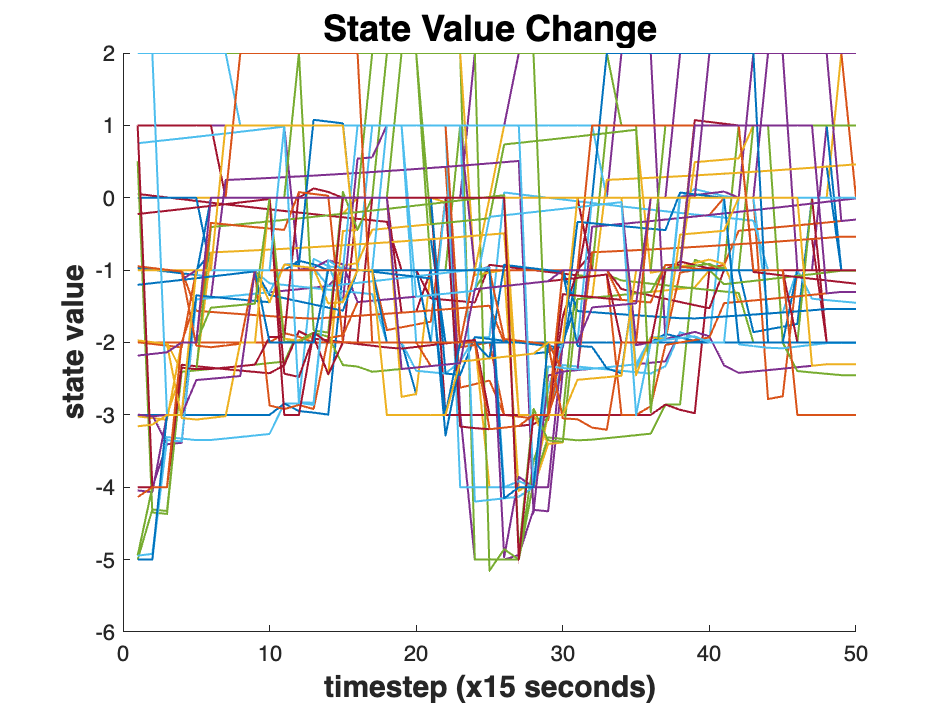

state_vector = 1:60;

state_change_value_matrix = zeros(length(time_index_vector),length(state_vector));

for time_index = time_index_vector
    for state_index = state_vector
        state_value_number = MDP.(['time' num2str(time_index)]).(['state' num2str(state_index)]).('state_value');
        state_change_value_matrix(time_index-min(time_index_vector)+1,state_index) = state_value_number;
    end
end
figure;
hold on
for state_index = state_vector
   plot(time_index_vector,state_change_value_matrix(:,state_index),'LineWidth',1)
end
hold off
title('State Value Change','FontSize',18,'FontWeight','bold')
xlabel('timestep (x15 seconds)','FontSize',15,'FontWeight','bold')
ylabel('state value','FontSize',15,'FontWeight','bold')

## IV. Propate the States from given start time and start state


arrival_state = 61:72;

start_time = 10;

start_state_vector = 1:60;

state_matrix = zeros(length(time_index_vector), length(start_state_vector));
reward_matrix = zeros(length(time_index_vector), length(start_state_vector));
cumulative_reward_matrix = zeros(length(time_index_vector), length(start_state_vector));
state_value_matrix = zeros(length(time_index_vector), length(start_state_vector));


for start_state = start_state_vector


[time_list, state_list, reward_list, cumulative_reward_list, state_value_list] = simulation_test(start_time,start_state,MDP,time_index_vector, arrival_state);

  for time_index = 1:length(time_list)
    state_matrix(time_list(time_index), start_state) = state_list(time_index);
  end
  
  t_0 = time_list(1);
  reward_matrix(t_0:t_0+length(reward_list)-1, start_state) = reward_list;
  cumulative_reward_matrix(t_0:t_0+length(cumulative_reward_list)-1, start_state) = cumulative_reward_list;
  state_value_matrix(t_0:t_0+length(state_value_list)-1, start_state) = state_value_list;

end

## V. Plot the Network Graph